# Control System Toolbox

Tools to manipulate LTI models

Classical analysis and design -Bode, Nyquist, Nichols diagrams -Step and impulse response -Gain/phase margins -Root locus design

Modern state-space techniques -Pole placement -LQG regulation

## LTI Objects (Linear Time Invariant)

4 basic types of LTI models

-Transfer Function (TF)

-Zero-pole-gain model (ZPK)

-State-Space models (SS)

-Frequency response data model (FRD)

Transfer Function ?Consider a linear time invariant (LTI) single-input/single-output system

y′′+6y′+5y=4u′+3u

?Applying Laplace Transform to both sides with zero initial conditions

num = [4 3]

num =        4              3       


den = [1 6 5]

den =        1              6              5       


sys1 = tf(num,den)

sys1 =
 
     4 s + 3
  -------------
  s^2 + 6 s + 5
 
연속시간 전달 함수입니다.



[num,den] = tfdata(sys1,'v')

num =        0              4              3       


den =        1              6              5       


alternatively

s=tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.



sys2=(4*s+1)/(s^2+6*s+5)

sys2 =
 
     4 s + 1
  -------------
  s^2 + 6 s + 5
 
연속시간 전달 함수입니다.



% Zero-pole-gain model 
% 
% 
% 

sys3 =  zpk(-0.75,[-1 -5],4) 

sys3 =
 
  4 (s+0.75)
  -----------
  (s+1) (s+5)
 
연속시간 영점/극점/이득 모델입니다.



[myzero,mypole,myk] = zpkdata(sys3,'v')

myzero =       -3/4     


mypole =       -1       
      -5       


myk =        4       


% 
% State-space model 
% 
% 
% 

sys4 = ss([0 1; -5 -6],[0;1],[3,4],0)

sys4 =
 
  A = 
       x1  x2
   x1   0   1
   x2  -5  -6
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   3   4
 
  D = 
       u1
   y1   0
 
연속시간 상태공간 모델입니다.



rss, drss - Random stable state-space models.

ss2ss - State coordinate transformation.

canon - State-space canonical forms.

ctrb - Controllability matrix.

obsv - Observability matrix.

gram - Controllability and observability gramians.

ssbal - Diagonal balancing of state-space realizations.

balreal - Gramian-based input/output balancing.

modred - Model state reduction.

minreal - Minimal realization and pole/zero cancellation.

sminreal - Structurally minimal realization.

## **Conversion between different models**

## Model Dynamics

pzmap: Pole-zero map of LTI models.

pole, eig: System poles

zero: System (transmission) zeros.

dcgain: DC gain of LTI models.

## Time Response of Systems

Impulse Response (impulse) 

Step Response (step) 

General Time Response (lsim) 

%clear;
s=tf('s');
G=(3*s+2)/(2*s^3+4*s^2+5*s+1)

G =
 
          3 s + 2
  -----------------------
  2 s^3 + 4 s^2 + 5 s + 1
 
연속시간 전달 함수입니다.



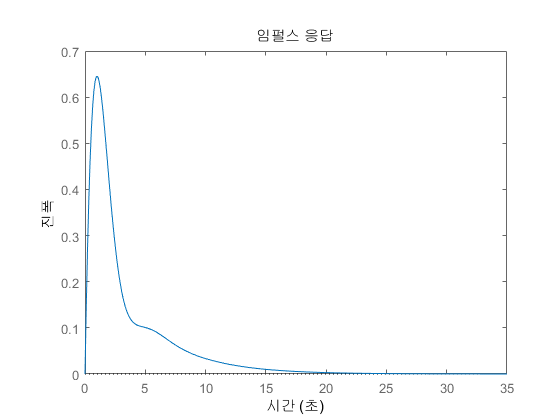

impulse(G)

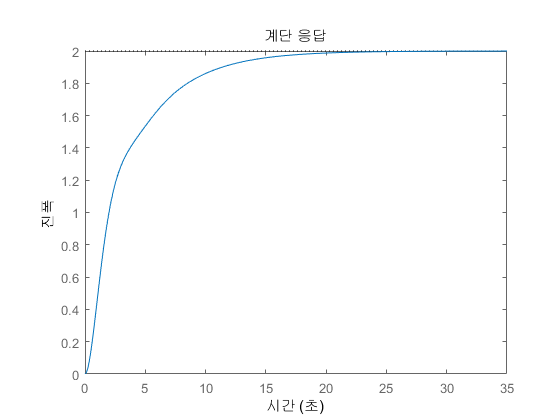


step(G)


t=0:0.1:35;
u=sin(0.5*t)

u =        0            120/2401       839/8404       133/890        209/1052       548/2215       409/1384       239/697        368/945       1137/2614       501/1045       887/1697      1153/2042      1867/3085       947/1470      1381/2026      1769/2466      1027/1367      2039/2603      1055/1297      1327/1577      3134/3613       598/671        994/1089        96/103       1916/2019       899/933       1045/1071       745/756       1771/1784      1991/1996      4624/4625      2344/2345       318/319       4402/4439       553/562        782/803        422/439        793/838       2563/2759       401/441        323/364       2297/2661       313/374       1199/1483      1171/1505       217/291       1048/1473      1203/1781       331/519        705/1178      1252/2245       848/1645       616/1305       871/2038       795/2083      1552/4633       163/567        306/1279       338/1775       441/3125       449/4909       141/3391      -109/12965     -298/5105      -235/2172      -5

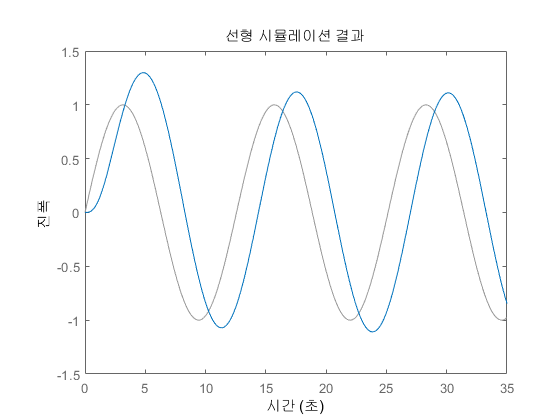

lsim(G,u,t)

Polynomial multiplication (conv) 

Polynomial division (deconv) 

Partial Fraction Expansion (residue) 

gensig - Generate input signal for lsim.